# HomeWork 14/04/2022

`Analizziamo ``L'homework`` passo per passo:`

`La funzione data` = $e^{-x} \cdot (cos(\frac {p \cdot x}{2}-\frac {\pi}{2})^2 + \frac {q}{1+2x^2}cos(2x)-3$

`sostituiamo i valori q e p inserendo la lunghezza del nostro nome e cognome `


$$e^{-x} \cdot (cos(\frac {14 \cdot x}{2}-\frac {\pi}{2})^2 + \frac {8}{1+2x^2}cos(2x)-3$$


`matricola: 0124002253`

`Nome: Riccardo Andrea, ``p = 14 `

`Cognome: Spinosa, ``q = 7 + 1 -> (Per preferenza personale dei numeri pari riverso 1 preso dallo spazio del nome al cognome per far uscire ambi pari)`

`Avviso`

`Spesso all'interno dell'homework commenterò e spiegherò i punti richiesti dalla traccia utilizzando la prima persona plurale considerando matlab il mio aiutante e compagno di avventura.`

***Punto 1.***

**definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete **`funrif`**;**

funrif= @(x) exp(-x).*(cos(14*x/2-pi/2)).^2+(8./(1+2*x.^2).*cos(2*x)-3);

*visualizziamo la nostra funzione sul grafico*

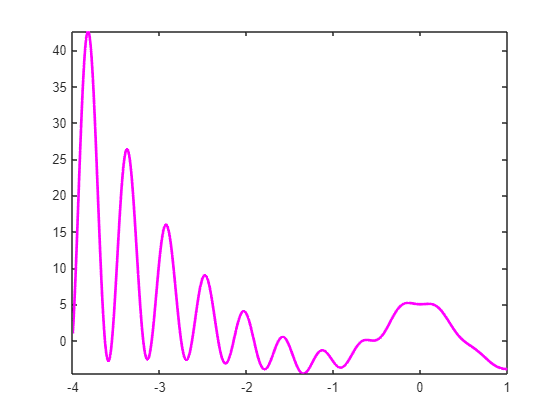

figure (1);
fplot(funrif,[-4,1],"color" , 'magenta','LineWidth',2)

***Spiegazione di ciò che abbiamo fatto: ***

*Abbiamo scritto la funzione in codice matlab, ed abbiamo rappresentato la funzione nell'intervallo consigliato grazie alla funzione fplot()  che prende in ingresso funrif e l'intervallo tra parantesi quadre che noi intendiamo rapprsentare, nel nostro caso -4,1.*

***Punto 2.***

**visualizzate il grafico della funzione di riferimento in **$[a,b]$**, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando **`text`**) gli estremi dell'intervallo scelto, i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *****punto di minimo 1*****), il secondo valore minimo e l'ascissa del secondo minimo (detta *****punto di minimo 2*****), il primo valore massimo e l'ascissa del primo massimo (detta *****punto di massimo 1*****), il secondo valore massimo e l'ascissa del secondo massimo (detta *****punto di massimo 2);***

*scegliamo il nostro intervallo e lavoriamoci sopra trovando i punti di minimo massimo e i 5 punti dove funrin =0*

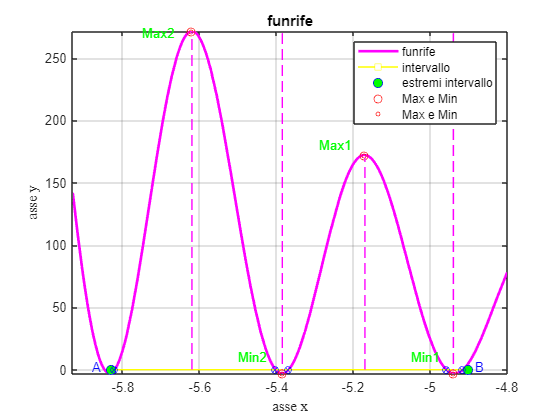

format long % impostiamo il formato  
figure (2)
fplot(funrif,[-5.93,-4.8],"color" , 'magenta','LineWidth',2) % rappresenta la funzione nel nostro grafico colorandola nel colore da noi scelto
title('funrife'); % da un titolo alla nostra rappresentazione del grafico
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
grid on;% creamo la griglia
set(gca, 'GridColor' ,[0 0 0]); % setta il colore della griglia da noi scelto, nel nostro caso in nero
% andiamo a scrivere con la funzione text() i min e max dell'intervallo e le fx=0
%yline(0,'color','black'); % creamo l'asse per vedere graficamente  dove il grafico funrin interseca
text(-4.885,2,'B', 'color','b') %scriviamo ad occhio la lettera b che indica la fine del nostro intervallo preso in esame
text(-5.88,2,'A', 'color','b') %scriviamo ad occhio la lettera di inizio del nostro intervallo preso in esame
text(-5.29,180,'Max1', 'color','green') %scriviamo ad occhio il nostro max
text(-5.05,10,'Min1', 'color','green') %scriviamo ad occhio il nostro min
text(-5.75,270,'Max2', 'color','green') %scriviamo ad occhio il nostro secondo max
text(-5.5,10,'Min2', 'color','green') %scriviamo ad occhio il nostro secondo min
hold on  %conserviamo i grafici negli assi correnti 


% iniziamo le rappresentazioni di ciò che abbiamo scritto
plot([-4.9,-5.83,],[0,0],'-s','color','y','MarkerFaceColor','w','markersize',6)%rappresentiamo con una linea il nostro intervallo
plot([-4.9,-5.83],[0,0],'o','markersize',7,'color','b','MarkerFaceColor','green')%marchiamo gli estremi del nostro intervallo a e b 


%scegliamo i punti guardandoli sopra al grafico per essere il piu precisi possibili
%marchiamo sul grafico i nostri minimi e massimi
plot([-5.17 -4.94],[172.163 -3.1],'or')
plot([-5.17 -4.94],[172.163 -3.1],'or','markersize',3)
plot([-5.62 -5.385],[271.5 -3.1],'or')
plot([-5.62 -5.385],[271.5 -3.1],'or','markersize',3)


%proiettiamo sull'asse i nostri massimi e minimi
%per gusto visivo rovesco le proiezioni dei minimi
plot([-5.17 -5.17],[0 170],'--','color', 'm')
plot([-5.62 -5.62],[0 270],'--','color', 'm')
plot([-4.94 -4.94],[270 0],'--','color', 'm')
plot([-5.385 -5.385],[270 0],'--','color', 'm')
% marchiamo come richiesto dalla traccia dove funrin è = 0
plot([-5.82074 -5.40225 -5.36857 -4.95861 -4.915 ],[0 0 0 0 0],'o','markersize',5,'color','blue')%marchiamo con una o i punti = 0
plot([-5.82074 -5.40225 -5.36857 -4.95861 -4.915 ],[0 0 0 0 0],'x','markersize',4.99,'color','blue')%marchiamo con una x i punti = 0 
% con questo sistema inseriremo la x dentro la o. 


hold off
legend('funrife','intervallo','estremi intervallo','Max e Min','Max e Min')

***Spiegazione di ciò che abbiamo fatto: ***

*Abbiamo visualizzato il grafico della funzione in un intervallo specifico grazie alla funzione fplot() che prende in ingresso la funzione chiamata funrif e specifica attarverso le parantesi quadre l'intervallo. successivamente abbiamo colorato la nostra funzione per farla risaltare di magenta, creato la griglia e settato il suo colore. Dando un occhiata alla funzione grazie alla funzione text() che prende in ingresso le coordinate x,y dove ci interessa scrivere il testo  abbiamo riportato tutti i punti di massimo e minimi presenti nell'intervallo preso in esame. Sempre grazie alla funzione text() abbiamo segnalato circa in maniera imprecisa l'intervallo preso da noi in esame con gli estremi A e B. Grazie ad hold on possiamo graficare ciò che abbiamo scritto nel nostro grafico con la funzione text. Iniziamo a graficare tutto con le funzioni plot() che prendono in ingresso le coordinate x,y.  Marchiamo con una linea rossa l'intervallo preso in esame e con due pallni colorati gli estremi a e b scelti precedentemente, dopo di che abbiamo marcato di rosso i nostri punti di minimo e massimo trovati nell'intervallo ed abbiamo proiettato sull'asse x sempre grazie al plot con una linea tratteggiata i punti di minimo e massimo della funzione nell'intervallo preso in esame. Nei punti di minimo siccome vicinissimi allo 0 abbiamo eseguito  proizioni inverse.  Per concludere eseguiamo il legend di ciò che vogliamo rappresentare. Così tutti i punti della traccia due richiesti sono stati eseguiti*

***Punto 3.***

**usate la function Matlab **`fzero`** per determinare i 5 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte; **

z1=fzero(funrif, [-4.90, -4.94])

z1 =   -4.914991086878006


z2=fzero(funrif, [-5, -4.95])

z2 =   -4.958088649198397


z3=fzero(funrif, [-5.36, -5.38])

z3 =   -5.368556655612669


z4=fzero(funrif, [-5.39,-5.41])

z4 =   -5.402306084118170


z5=fzero(funrif,-5.83)

z5 =   -5.821053141368261


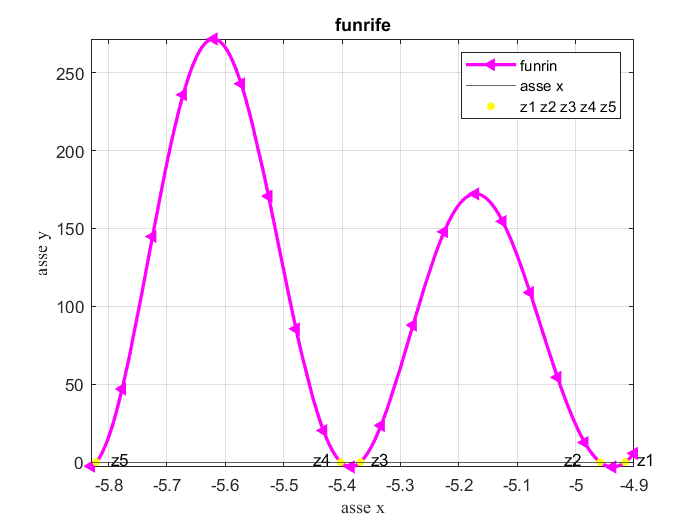

figure(3);
%troviamo gli 0 della funzione
fplot(funrif,[-5.83,-4.9],'m<-',"color" , 'magenta','markersize',4,'LineWidth',2)
yline(0);
title('funrife'); % da un titolo alla nostra rappresentazione del grafico
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
text(-4.895,2,'z1', 'color','k') %scrive un testo sulla nostra funzione
text(-5.02,2,'z2', 'color','k')%scrive un testo sulla nostra funzione
text(-5.350,2,'z3', 'color','k')%scrive un testo sulla nostra funzione
text(-5.45,2,'z4', 'color','k')%scrive un testo sulla nostra funzione
text(-5.795,2,'z5', 'color','k')%scrive un testo sulla nostra funzione
grid on;% creamo la griglia


hold on
plot([z1, z2, z3, z4, z5],[0, 0, 0, 0, 0],'.','markersize',16,'color','y')% grafichiamo le nostre 0 sul grafico
hold off
legend('funrin','asse x','z1 z2 z3 z4 z5')

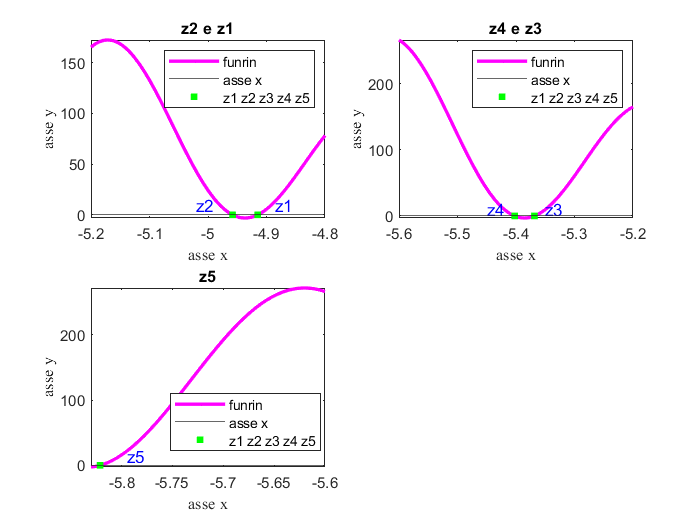


%grafichiamo ogni ritrovamento passo passo degli 0 della funzione spezzettando quest'ultima.
% analizziamoli da piu' vicino

figure(4)
%z2 e z1
subplot(221),fplot(funrif,[-5.2,-4.8],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('z2 e z1')%diamo un titolo
yline(0)%creamo l'asse delle x
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([z1,z2],[0,0],'.','markersize',12,'color','green')% marca il punto di nostro interessa sul grafico della funzione
text(-4.885,10,'z1', 'color','b');%scrive un testo sulla nostra funzione
text(-5.02,10,'z2', 'color','b');%scrive un testo sulla nostra funzione
hold off
legend('funrin','asse x','z1 z2 z3 z4 z5')
%z4 e z3
subplot(222),fplot(funrif,[-5.6,-5.2],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('z4 e z3');%diamo un titolo
yline(0)%creamo l'asse delle x
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([z3,z4],[0 0],'.','markersize',12,'color','green')% marca il punto di nostro interessa sul grafico della funzione
text(-5.350,10,'z3', 'color','b')%scrive un testo sulla nostra funzione
text(-5.45,10,'z4', 'color','b')%scrive un testo sulla nostra funzione
hold off
legend('funrin','asse x','z1 z2 z3 z4 z5')
% z5
subplot(223),fplot(funrif,[-5.83,-5.6],"color" , 'magenta','LineWidth',2) % permette di esporre tracciati multipli nella stessa finestra
title('z5');%diamo un titolo
yline(0)%creamo l'asse delle x
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot((z5),(0),'.','markersize',12,'color','green')% marca il punto di nostro interessa sul grafico della funzione
text(-5.795,15,'z5', 'color','b')%scrive un testo sulla nostra funzione
hold off
legend('funrin','asse x','z1 z2 z3 z4 z5','location','best')

***Spiegazione di ciò che abbiamo fatto: ***

*Abbiamo visualizzato il grafico della funzione in un intervallo specifico grazie alla funzione fplot() che prende in ingresso la funzione chiamata funrin e specifica attarverso le parantesi quadre l'intervallo. Abbiamo settato il colore e personalizzato la funzione. La traccia richiedeva di trovare tutti i punti in cui funrin fosse = 0 e ciò lo abbiamo fatto grazie alla function fzero() che prende in ingresso la funzione funrin e il punto da cui partire per calcolarsi lo 0, in alcune circostanze è stato necessario passare un intervallo di valori per farlo convergere allo 0 desiderato. Non abbiamo fatto altro che rappresentare gli 0 trovati nel grafico segnalandoli con opportuni colori e grazie alla function subplot() che * permette di esporre **tracciati multipli nella stessa finestra. **Così*Tutti i punti della traccia richiesti sono stati eseguiti. *

***Punto 4.***

**determinate un'approssimazione dei 5 zeri, usando il metodo di bisezione (nostra function **`bisezione`**) per lo zero più piccolo, il metodo delle Secanti (nostra function **`Secanti`**) per il secondo e terzo zero  e il metodo di Newton (nostra function **`Newton`**) per il quarto e il quinto zero (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;**

***Spiegazione algoritmo del metodo di Bisezione.***

*Il problema da un punto di vista matematico può essere posto nella notazione f(x) = 0 dove f è una funzione nota di  una variabile. Risolvere questo problema significa trovare se esiste un numero x tale che f(x) = 0 ed x è un numero reale. Il metodo di bisezione è un algoritmo iterativo globale e a velocità di convergenza lineare. Tale algoritmo risulta vincente solo se  f è una funzione continua e se si conosce un intervallo che  contiene la soluzione. L’errore si riduce di un fattore costante ad ogni passo ovvero la nuova approssimazione avrà un bit corretto  in più rispetto all’approssimazione precedente. L’intestazione è function radice=bisezione(funzione,a,b,delta_ass), il primo argomento di input deve essere l’handle il secondo e il terzo sono gli estremi dell’intervallo iniziale, l’ultimo argomento è  l’accuratezza che si vuole sul risultato da calcolare e a tale accuratezza dovrà essere aggiunta l'eps(). L'idea è quella di ripetere il ciclo while fino  a che la somma degli estremi A e B dei due intervalli sia  maggiore dell'accuratezza da noi designata(delta_ass)+ eps->(da non sottovalutare l'importanza di tale aggiunta), dentro al corpo del while calcoleremo il punto medio, la funzione in quel punto e ne confronteremo il segno con la funzione dell'estremo A calcolata in quel punto, se diverso l'estremo B diventerà il nostro punto medio così raggiungendo la metà dell'intervallo e di conseguenza ricalcoleremo la funzione in quel punto, viceversa non ci sposteremo verso sinistra ma destra e pertanto il nostro estremo A diventerà uguale al nostro punto medio e ne verrà ricacolata la funzione in quel punto. Da notare bene la logica costruita dietro, per spiegarlo in maniera banale e renderre chiaro il concetto userò esempi di scuola elementare che hanno il puro scopo di rendere chiara l'idea, ma da notare bene che la costruzione della function non corrisponderà assolutamente all'esempio proposto. Supponiamo di avere un valore x=10, e che noi stiamo ricercando un qualsiasi valore positivo 0 < k< 10, tale valore noi non lo conosciamo per tanto non possiamo sapere quale sia, ma possiamo spostarci al risultato in maniera piu precisa e logica possibile, tale numero sara il punto medio in questo caso 5. Tale soluzione banale può essere rafforzata attraverso un ragionamento logico elementare, da notare bene che codesto è solo un esempio e non corrisponde all'algoritmo!. Se noi scegliessimo un valore diverso da 5, il nostro margine di errore potrebbe risultare piu elevato perchè la soluzione potrebbe trovarsi all'estremo opposto, scegliendo il punto medio i due estremi saranno equodistanti e pertanto la soluzione data considerandola errata sarà sia alla sua sinistra che alla sua destra uguale e dello stesso margine di errore. La mia soluzione sarebbe obbligatoriamente e matematicamente sempre nel caso peggiore distante di 4 unità, se il numero cercato fosse l'estremo valore sinistro ovvero 1 il mio margine di errore corrisponderà sempre a 4; 9-5=4; viceversa se scegliessi invece 9 e non il punto medio, nel caso la soluzione fosse 1 avrei il doppio margine di errore: 9-1=8; . L'algoritmo segue tale logica elementare applicandolo in un contesto molto più complesso ridefinendo il nostro intervallo ad ogni passo confrontando il segno indicandoci la direzione dell'intervallo prossimo da considerare  portandoci ad ogni passo sempre più vicino alla soluzione.*

*Da considerara con una certa importanza che una funzione  può presentare un comportamento da analizzare con attenzione  Per esempio, la funzione può avere più soluzioni, in questo caso si necessita determinare quella a cui siamo interessati. Un altro aspetto da considerare è la  molteplicità delle soluzioni. Bisogna prestare particolare attenzione  quando la risoluzione del problema viene calcolata in un sistema  aritmetico a precisione finita che rappresenterà "piccoli" errori nelle funzioni. Nel Caso specifico del metodo di bisezione ad ogni passo  si ha un intervallo che contiene la soluzione, si calcolerà il punto medio dell’intervallo che di fatto porterà ad un bit corretto in più ad ogni iterazione.*

* I matematici Ruffini, Abel e il francesce, Galois hanno indipendentemente dimostrato dando vita al  Teorema Fondamentale dell'Algebra che non esiste una  formula chiusa  per calcolare gli zeri di un qualunque polinomio di grado >=5. L'algoritmo di bisezione è in grado di approssimare la soluzione mediante una formula ricorrente dando vita ad una successione di soluzioni. Gli algoritmi basati su formule ricorrenti si chiamano algoritmi iterativi e  questi devono, ad un certo  punto dell'esecuzione, necessariamente arrestarsi. ,**** la prima cosa da fare e  localizzare la soluzione d'interesse oppure  determinare un intervallo che contiene solo una soluzione. ****Quello che possiamo dire è  che l'errore al passo k è minore o uguale della metà dell'errore al passo precedente k-1 e che il metodo viene detto metodo globale perchè sempre convergente. *

**Intestazione function**

*function radice=bisezione(funzione,a,b,delta)*

*Verifichiamo che il risultato della function fzero() di matlab corrisponde al risultato della nostra function bisezione().*

delta_ass = 1e-6;
radice1 = bisezione(funrif,-4.90, -4.94,delta_ass)

radice1 =   -4.914991149902344


z1% richiamo z1 per confrontare ambe le soluzioni del metodo di bisezione e fzero.

z1 =   -4.914991086878006


*I risultati corrispondono ai risultati sperati*

*Esempio Grafico Di Bisezione su z1*

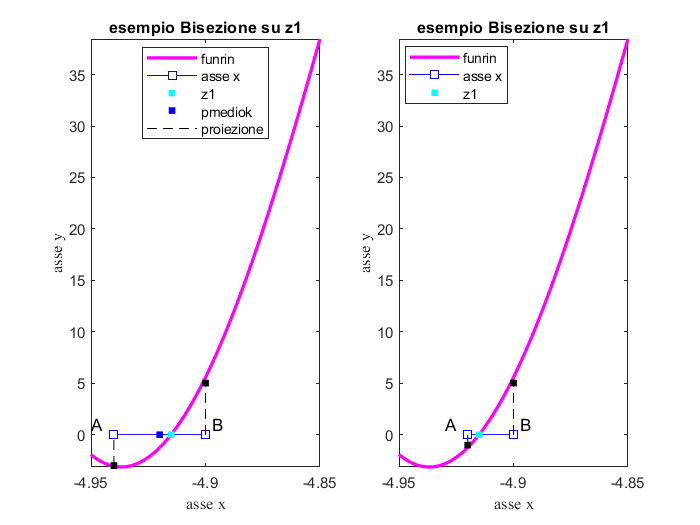

figure(5)
pmediok=(-4.90-4.94)/2;
% z1
subplot(121),fplot(funrif,[-4.95,-4.85],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('esempio Bisezione su z1');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([-4.90,-4.94],[0,0],'-s','color','b','MarkerFaceColor','w','markersize',6)
plot((z1),(0),'.','markersize',12,'color','c')
plot((pmediok),(0),'.','markersize',12,'color','b');% marca il punto di nostro interessa sul grafico della funzione
text(-4.95,1,'A', 'color','k');%scrive un testo sulla nostra funzione
text(-4.897,1,'B', 'color','k');
plot([-4.90,-4.90],[0 5],'--','color', 'k')
plot([-4.94,-4.94],[-3 0],'--','color', 'k')
plot((-4.90),(5.01),'.','markersize',12,'color','k')
plot((-4.94),(-3),'.','markersize',12,'color','k')
hold off
legend('funrin','asse x','z1','pmediok','proiezione','location','best')
subplot(122),fplot(funrif,[-4.95,-4.85],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('esempio Bisezione su z1');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([-4.90,pmediok],[0,0],'-s','color','b','MarkerFaceColor','w','markersize',7)
plot((z1),(0),'.','markersize',12,'color','c');% marca il punto di nostro interessa sul grafico della funzione
text(-4.93,1,'A', 'color','k');%scrive un testo sulla nostra funzione
text(-4.897,1,'B', 'color','k');
plot([-4.90,-4.90],[0 5],'--','color', 'k')%proiezione sul grafico
plot([pmediok,pmediok],[-1 0],'--','color', 'k')%proiezione sul grafico
plot((-4.90),(5.01),'.','markersize',12,'color','k')
plot((pmediok),(-1.01),'.','markersize',12,'color','k')
hold off
legend('funrin','asse x','z1','location','best')

**Spiegazione del metodo delle Secanti**

*Il metodo delle Secanti usa una formula ricorrente del  secondo ordine e  può essere paragonato al medoto di Newton tuttavia non prende in ingresso la derivata' che invece nel metodo Newton è indispensabile. Analogamente Invece di usare la derivata utilizza la pendenza della retta secante. L'algoritmo delle secanti è un metodo locale a convergenza superlineare, con superlieare si intende che, a ogni  passo di iterazione, l’errore relativo si riduce diventando una  potenza dell’errore  precedente. L'esponente della potenza è un numero compreso tra 1 e 2 e nel caso specifico del metodo delle secanti il numero è 1.618..., tale numero è noto come sezione aurea. L'idea è molto simile a  quella di Newton, ma il meccanismo per determinare a ogni passo la retta che approssima il problema non lineare è   diverso dato che invece di usare la tangente si utilizza una secante. .Consideriamo due punti x1 e x2, bisogna calcolare la retta secante in codesti due punti e considerare come nuovo punto, il punto in cui interseca tale retta con l'asse delle x. Immaginiamo che il nostro fx=0 si trovi alla sinistra dei due punti presi in considerazione x1 e x2, calcolandoci la retta secante in questi due punti la retta intersecherà nell'asse x, ed il punto in cui interseca la retta diventerà la nuova nostra  successiva approssimazione. Così x1 diventerà il nostro nuovo x2 e il punto in cui interseca la secante diventerà il nostro nuovo x1, procederemo così in maniera iterativa fino a rispettare il nostro criterio d'arresto. Si noti che se l’approssimazione iniziale x0 ha una cifra corretta, dopo 6 passi di iterazione si otterrà una nuova  approssimazione con 16 cifre corrette.L’intestazione è function è: function radice = Secanti(funzione,xiniz,xiniz1,delta_ass,kmax) Il metodo prende in input come primo argomento l’handle, il  secondo e il terzo argomento sono le prime due approssimazioni iniziali, il quarto argomento è  l’accuratezza da noi assegnata il quale bisgnerà sommare eps(), l'ultimo è il numero di iterazioni consentite. l'interno del ciclo while riferendosi ai nomi delle variabili presenti nella function  viene perso il vecchio valore di xk1 e viene sostituito dal valore corrente  di xk. Viene determinato il nuovo valore corrente xk, applicando la  correzione rivalutando sia la funzione che la pendenza della secante. All'uscita dal ciclo while l'approssimazione  corrente viene restituita in "radice". *

radice2 = Secanti(funrif,-5,-4.95,delta_ass,20)

radice2 =   -4.958088553412159


z2

z2 =   -4.958088649198397


radice3 = Secanti(funrif,-5.36, -5.38, 1e-7, 20)

radice3 =   -5.368556657370651


z3

z3 =   -5.368556655612669


*I risultati corrispondo ai risultati attesi.*

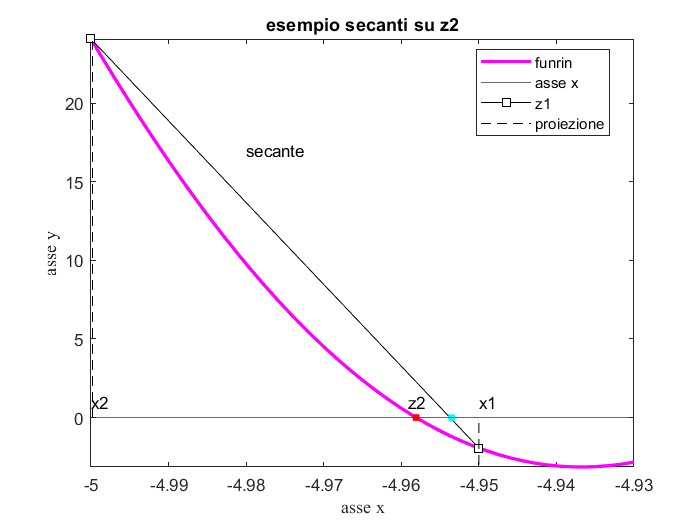

figure(6)
fplot(funrif,[-5,-4.93],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('esempio secanti su z2');%diamo un titolo
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
hold on
yline(0)%traccia l'asse delle x
text(-4.95,1,'x1', 'color','k')%scrive un testo sulla nostra funzione
text(-5,1,'x2', 'color','k')
text(-4.98,17,'secante', 'color','k')
plot([-4.95,-5],[funrif(-4.95),funrif(-5)],'-s','color','k','MarkerFaceColor','w','markersize',6)
plot([-4.9998,-4.9998],[0 24],'--','color', 'k');%proietta x1
plot([-4.95,-4.95],[-3 0],'--','color', 'k')%proietta x2
plot((-4.9535),(0),'.','markersize',12,'color','c')
plot((z2),(0),'.','markersize',12,'color','r')
text(z2-0.001,1,'z2', 'color','k');%scrive testo sul grafico
hold off
legend('funrin','asse x','z1','proiezione','location','best')

**Spiegazione dell'algoritmo Di Newton**

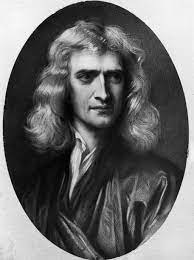* Il metodo di Newton è un algoritmo iterativo locale  a velocità di convergenza quadratica che  risolve il problema f(x) = 0; Necessittà di conoscere una buona approssimazione iniziale e f deve essere una funzione continua derivabile. Essendo un metodo locale l'algoritmo non convergerà sempre.Per avere la condizione sufficiente per la convergenza   la funzione ha derivata prima diversa da zero in un intervallo  [a,b] (il ché significa che la funzione non ha minimi e massimi locali nell'intervallo [a,b] ossia che la tangente non è  mai parallela all'asse delle x ) e se f'' non cambia segno nell'intervallo [a,b] ( cioè f non cambia di concavità ossia non  ha punti di flesso) e se la f cambia di segno in [a,b] e risulta inoltre che*$\left|f\left(a\right)/f\prime \left(a\right)\right|<\left(b-a\right)e\left|f\left(b\right)/f\prime \left(b\right)\right|<\left(b-a\right)\;$*allora il  metodo di Newton converge per qualsiasi scelta di x0 appartenente all'intervallo [a,b]. A ogni passo di iterazione, l’errore relativo si riduce diventando il quadrato dell’errore  precedente. Il metodo di Newton usa i valori della f e della sua derivata prima f'. Ricordiamo la formula portante di tale metodo: *$x\left(k+1\right)-f\left(\textrm{xk}\right)/f\prime \left(\textrm{xk}\right)\ldotp$* L'approssimazione al passo x(k+1) è data dalla differenza tra l'approssimazione al passo xk e la quantità f(xk)/f'(xk). occorre conoscere a priori f, ed f'. dev'essere nota l'approssimazione iniziale. In ingresso prende il  parametro puntatore alla function che sarà la funzione che noi vogliamo prendere in esame e calcolarne lo 0, la derivata, xiniz è la  prima approssimazione della successione delle approssimazioni, 'delta_ass'  e kmax che è il numero massimo di iterazioni consentite.  Il criterio di arresto del ciclo while è simile a quello presentato per il metodo di bisezione, all'interno viene calcolata la nuova approssimazione  sommando ad xk, il valore correzionek, successivamente viene valutata la funzione nuovamente nei punti di nostro interesse e verrà poi infine incrementato il contatore.  Questo è un paradigma generale del calcolo scientifico. Se un problema è non lineare (difficile) questo viene risolto in  maniera approssimata risolvendo una successione di problemi facili. Il metodo di Newton risolve tale problema  in una successione di problemi lineari, dunque viene risolto, in maniera iterativa. Si parte dunque dall'approssimazione iniziale di x0. Attorno x0, la funzione viene approssimata dalla retta tangente che risolverà al passo k il problema t(x)=0 avvicinando la nostra tangente sempre più alla soluzione.Pertanto, il metodo di Newton, a ogni iterazione,approssima localmente (cioè in un intorno del punto xk ) la funzione f(x) con una retta t(x). in un triangolo rettangolo con cateti a e b, la lunghezza del cateto a è uguale al rapporto tra la lunghezza del cateto b e la tangente dell’angolo opposto al cateto b.L'intestazione della function è:  function radice = Secanti(funzione,xiniz,xiniz1,delta_ass,kmax).*

**Derivata calcolata con funtool:**


$$- cos(7x - \frac{\pi}2)^2\cdot exp(-x) - \frac{(16\cdot sin(2x))}{(2x^2 + 1)} - \frac{(32x\cdot cos(2x))}{(2x^2 + 1)^2} - 14 \cdot cos(7x -  \frac {\pi}{2})\cdot sin(7x -  \frac{\pi}{2})\cdot exp(-x)$$


derivata_prima = @(x) - cos(7.*x - pi/2).^2.*exp(-x) - (16*sin(2.*x))./(2.*x.^2 + 1) - (32.*x.*cos(2.*x))./(2.*x.^2 + 1).^2 - 14*cos(7.*x - pi/2).*sin(7.*x - pi/2).*exp(-x);
 radice5=Newton(funrif,derivata_prima,-5.83,1e-7,20)

radice5 =   -5.821053141364522


z5

z5 =   -5.821053141368261


 radice4=Newton(funrif,derivata_prima,-5.4,delta_ass,20)

radice4 =   -5.402306084149923


 z4

z4 =   -5.402306084118170


*I risultati ottenuti corrispondo ai risultati sperati.*

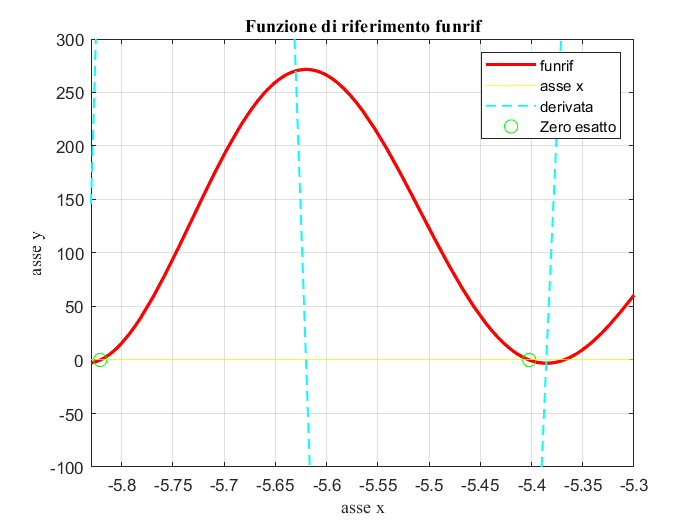

 %Rappresentiamo la derivata
 figure (7)
 fplot(funrif,[-5.83,-4.9],'r',"color" , 'r','markersize',2,'LineWidth',2)%rappresenta il grafico
 hold on   
 grid on %crea la griglia
 xlabel("asse x",'FontName','Times New Roman') %scrive l'asse x esternamente al grafico
 ylabel("asse y",'FontName','Times New Roman')
 title("Funzione di riferimento funrif",'FontName','Times New Roman') %da un titolo al grafico
 yline(0,'-','color','y')
 fplot(derivata_prima,[-5.83,-4.9],"--","LineWidth",1,'color','c') %rappresenta la derivata sulla nostra funzione
 axis([-5.83 -5.3 -100 300])

plot([z4,z5],[0,0],'o','markersize',8,'color','g')
hold off
legend('funrif','asse x','derivata', 'Zero esatto')

*Da notare come la derivata assume valori altissimi.*

***Spiegazione di ciò che abbiamo fatto: ***

*Dopo esserci calcolati nel punto 3 gli 0 della funzione abbiamo applicato i metodi da noi conosciuti Newton secanti e bisezione per ricalcolarceli per poi mettere a confronto i risultati delle nostre funzioni con quelle calcolate da matlab attraverso fzero(). Ad ogni Metodo proposto e stata fatta una rappresentazione grafica ad occhio visiva di ciò che accade, da notare che potremmo cominciare a capire se il problema e ben condizionato calcolando il valore assoluto della derivata prima nel punto considerato e del valore assoluto della funzione nel suddetto punto.*

***Punto 5. ***

**considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con le Secanti), sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con Newton) e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei cinque zeri;**

***Calcoliamo gli errori assoluti.***

%PRIMO ZERO CON ZERO DI BISEZIONE
err1= abs(radice1-z1)

err1 =      6.302433774862948e-08


err1<delta_ass %CONTROLLO

ans = logical
   1


*Calcolato l'errore assoluto  e successivamente lo confronto delta_ass, noto che tale confronto ha restituito un valore booleano = 1. Pertanto il confronto fatto è vero e l'errore assoluto è minore dell'accuratezza richiesta.*


%SECONDO ZERO CON ZERO DI SECANTE
err2= abs(radice2-z2)

err2 =      9.578623849648693e-08


err2<delta_ass %CONTROLLO LOGICO

ans = logical
   1


*Calcolato l'errore assoluto  e successivamente lo confronto delta_ass, noto che tale confronto ha restituito un valore booleano = 1. Pertanto il confronto fatto è vero e l'errore assoluto è minore dell'accuratezza richiesta.*


%TERZO ZERO CON ZERO DI SECANTE
err3= abs(radice3-z3)

err3 =      1.757982204253494e-09


err3<delta_ass %CONTROLLO LOGICO

ans = logical
   1


*Calcolato l'errore assoluto  e successivamente lo confronto delta_ass, noto che tale confronto ha restituito un valore booleano = 1. Pertanto il confronto fatto è vero e l'errore assoluto è minore dell'accuratezza richiesta.*


%QUARTO ZERO CON ZERO DI NEWTON
err4= abs(radice4-z4)

err4 =      3.175326668269918e-11


err4<delta_ass %CONTROLLO LOGICO

ans = logical
   1


*Calcolato l'errore assoluto  e successivamente lo confronto delta_ass, noto che tale confronto ha restituito un valore booleano = 1. Pertanto il confronto fatto è vero e l'errore assoluto è minore dell'accuratezza richiesta.*


%QUINTO ZERO CON ZERO DI NEWTON
err5= abs(radice5-z5)

err5 =      3.739231146937527e-12


err5<delta_ass %CONTROLLO LOGICO

ans = logical
   1


*Calcolato l'errore assoluto  e successivamente lo confronto delta_ass, noto che tale confronto ha restituito un valore booleano = 1. Pertanto il confronto fatto è vero e l'errore assoluto è minore dell'accuratezza richiesta.*

***Calcoliamo i residui***

*Se una funzione è data nella forma 1/f(z) , con f olomorfa, tale che f(z0)=0 , e f non identicamente nulla intorno a z0 , allora f ha uno zero d'ordine finito in z0 (per il Principio d'identità delle funzioni analitiche); detto p l'ordine di z0 come zero di f , allora la funzione 1/f(z) ha in z0 un polo d'ordine p .*

*L'ordine di uno zero di una funzione olomorfa si determina o sviluppando esplicitamente in serie di Taylor (in tal caso l'ordine dello zero è l'indice del primo coefficiente non nullo nello sviluppo), oppure calcolando le derivate e fermandosi alla prima derivata non nulla (in tal caso l'ordine dello zero coincide con l'ordine della prima derivata non nulla).*

*Il residuo indica quanto la soluzione soddisfa il problema. Se l’indice di condizionamento non è grande, allora l’errore è dello stesso ordine di  grandezza del residuo. Il residuo dell’approssimazione ris è immediatamente calcolabile valutando la f in ris*

*Da notare è  che un residuo di modesta entità non implica necessariamente che l'errore sia modesto.  Nel caso dell'algoritmo di Newton Globale non presentato nella traccia si noti come esempio venga usato il residuo assoluto come criterio di arresto denominato ress_ass.*

residuo1= abs(funrif(radice1))%calcolo il residuo sul metodo di bisezione 

residuo1 =      1.785854177649426e-05


residuo1<delta_ass 

ans = logical
   0


*Si noti che il residuo è un numero di un  ordine maggiore dell’accuratezza richiesta (1e-6) , ed è  una approssimazione di 0 con 6 cifre corrette, notare che il residuo è maggiore di delta_ass, inoltre il residuo è dell'ordine e-05 su una accuratezza di 1e-6 indica un residuo accettabile.*

residuo2= abs(funrif(radice2))%calcolo il residuo sul metodo secante

residuo2 =      2.835724180894061e-05


residuo2<delta_ass

ans = logical
   0


residuo1<err1

ans = logical
   0


*il valore logico è falso*

*Si noti che il residuo è un numero di  ordine maggiore dell’accuratezza richiesta (1e-6) , ed è  una approssimazione di 0 con 6 cifre corrette, notare che il residuo è maggiore di delta_ass,  inoltre il residuo è dell'ordine e-05 su una accuratezza di 1e-6 indica un residuo accettabile.*

residuo2<err2

ans = logical
   0


*il valore logico è falso.*

residuo3= abs(funrif(radice3))%calcolo il residuo sul metodo secante

residuo3 =      6.177495719406068e-07


residuo3<delta_ass

ans = logical
   1


*Si noti che il residuo è un numero di ordine minore dell’accuratezza richiesta (1e-6) , ed è  una approssimazione di 0 con 6 cifre corrette, notare che il residuo è minore di delta_ass.*

residuo3<err3

ans = logical
   0


*il valore logico è falso.*

residuo4= abs(funrif(radice4))%calcolo il residuo sul metodo di Newton

residuo4 =      1.154499695843469e-08


residuo4<delta_ass

ans = logical
   1


*Si noti che il residuo è un paio di ordini minore dell’accuratezza richiesta (1e-6) , ed è  una approssimazione di 0 con 6 cifre corrette, notare che il residuo è maggiore di delta_ass.*

residuo4<err4

ans = logical
   0


*il valore logico è falso.*

residuo5= abs(funrif(radice5))%calcolo il residuo sul metodo di Newton

residuo5 =      1.627379564439480e-09


residuo5<delta_ass

ans = logical
   1


*Si noti che il residuo è di ordine maggiore dell’accuratezza richiesta (1e-6) , ed è  una approssimazione di 0 con 6 cifre corrette, notare che il residuo è maggiore di delta_ass.I residui sono tutti maggiori degli errori assoluti, in un problema ben condizionato il residuo è uno stimatore dell'errore.*

residuo5<err5 

ans = logical
   0


*il valore logico è falso.*

*Analizziamo La funzione.*

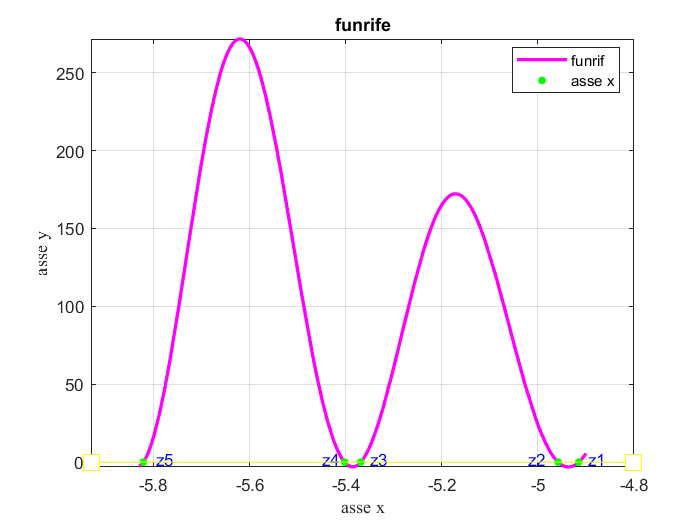

figure(8)
fplot(funrif,[-5.83,-4.9],"color" , 'magenta','LineWidth',2)
title('funrife'); % da un titolo alla nostra rappresentazione del grafico
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
text(-4.895,2,'z1', 'color','b'); %scrive un testo sulla nostra funzione
text(-5.02,2,'z2', 'color','b')%scrive un testo sulla nostra funzione
text(-5.350,2,'z3', 'color','b')%scrive un testo sulla nostra funzione
text(-5.45,2,'z4', 'color','b')%scrive un testo sulla nostra funzione
text(-5.795,2,'z5', 'color','b')%scrive un testo sulla nostra funzione
grid on
hold on 
plot([z1, z2, z3, z4, z5],[0, 0, 0, 0, 0],'.','markersize',16,'color','green')% grafichiamo le nostre 0 sul grafico
plot([-4.8,-5.93],[0,0],'-s','color','y','MarkerFaceColor','w','markersize',13) 
hold off
legend('funrif','asse x','location','best')

*Guardando il grafico della funzione di riferimento, per ognuno dei cinque zeri, il problema appare ben condizionato, cio' si deduce dalla pendenza della funzione nel punto 0,che appunto graficamente non risulta eccessiva, l'intervallo di errore che risulta dalla pendenza della funzione nel punto risulta minore se la pendenza è ridotta, al contrario risulta maggiore se la pendenza è molto grande.*

*Calcoliamo gli indici di condizionamento*

*Un concetto molto rilevante dell’Calcolo Scientifico: il condizionamento di un problema. Nella risoluzione di un problema matematico e in molti casi utile ` avere una misura di quanto i risultati siano sensibili a piccoli cambiamenti dei dati iniziali. In generale se a “piccoli” cambiamenti nei dati iniziali corrispondono “grandi” cambiamenti nei dati finali diremo che il problema e` mal condizionato. In caso contrario diremo che e` ben condizionato. La quantita responsabile dell’amplificazione degli errori nei dati ` iniziali si chiama indice di condizionamento. Un problema si considera ben condizionato quando la soluzione , non diversifica molto dalla soluzione del problema originale; un problema risulta invece mal condizionato se  un problema le cui  soluzioni sono  sensibili a piccole perturbazioni dei dati iniziali. *

*Dal punto di vista quantitativo *$\textrm{kf}\left(r\right)=\left(f\prime ˆ-1\right)$,* Se una funzione presenta una derivata vicino alla soluzione piccola significa che il problema e mal condizionato. quanto piu grande è l'indice di condizionamento piu il problema è mal condizionato. *

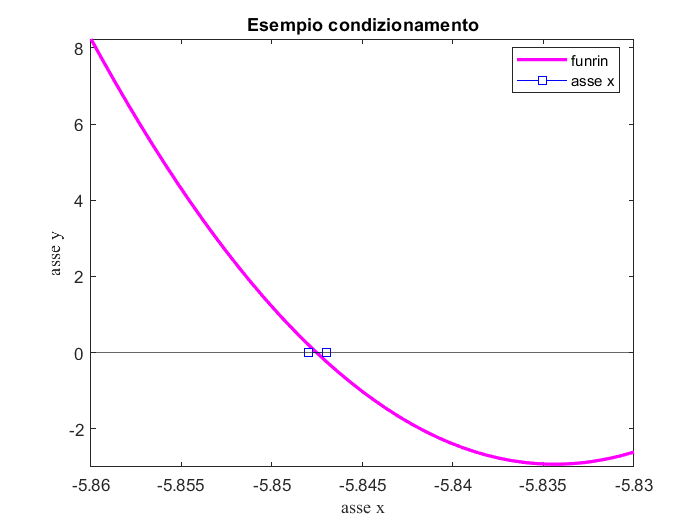

figure(9)
fplot(funrif,[-5.86,-5.83],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('Esempio condizionamento')%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([-5.848, -5.847],[0,0],'-s','color','b','MarkerFaceColor','w','markersize',6)
yline(0);
hold off
legend('funrin','asse x','location','best');

*Prima di Procedere con il calcolo, possiamo definire dall'esempio fatto con il grafico che il problema nel punto z5 è ben condizionato e presenterà un ottimo indice di condizionamento, detto in parole povere nel punto in cui interseca  la nostra funzione nell'asse x la pendenza è alta. *

*Procediamo con il calcolo.*

condizionamento1= 1/abs(derivata_prima(z1))%condizionamento primo 0 metodo di bisezione

condizionamento1 =    0.003529081678389


condizionamento2= 1/abs(derivata_prima(z2))%condizionamento secondo 0 metodo secanti

condizionamento2 =    0.003377832833436


condizionamento3= 1/abs(derivata_prima(z3))%condizionamento terzo 0 metodo secanti

condizionamento3 =    0.002845782753016


condizionamento4= 1/abs(derivata_prima(z4))%condizionamento quarto 0 metodo di Newton

condizionamento4 =    0.002750387211608


condizionamento5= 1/abs(derivata_prima(z5))%condizionamento quinto 0 metodo di Newton

condizionamento5 =    0.002298200353187


*Notiamo che gli indici di condizionamento non sono grandi dunque i problemi risultano ben condizionati, e *allora l’errore è dello stesso ordine di  grandezza del residuo.

***Spiegazione di ciò che abbiamo fatto***

 *Per calcolare l'errore assoluto siamo andati a calcolare l'errore sottraendo il nostri 0 calcolati attarverso le nostre function "bisezione, secanti, newton" allo 0 calcolato attraverso la function di matlab e poi abbiamo effettuato un semplice controllo logico per verificare che siano minori dell'accuratezza da noi richiesta.*

*Per calcolare i resuidi, per  verificare quanto è ottimale la soluzione approssimata verifichi il problema, abbiamo eseguito la function abs() per restituire il valore assoluto della funzione funrif calcolata nei vari 0 restituiti dalle function proposte. Abbiamo graficato ed analizzato la funzione e successivamente calcolato gli indici di condizionamento. *

***Punto 6.***

**osservando il grafico della vostra funzione di riferimento nell'intervallo **$[a,b]$**e della bisettrice, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function **`PFisso (suggerimento: `**usate opportunamente**` fzero)`**, calcolate una approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, cioè più vicino ad **$a$**, e determinate il residuo; dite se il metodo del punto fisso convergerebbe a tale punto fisso.**

`procediamo`

*Per trovare i punti fissi della  funzione di riferimento dell'intervallo A e B  bisogna creare la bisettrice(che è una retta/semiretta che passa per gli stessi punti, ovvero hanno ordinate ed ascisse uguali) e proiettarla nell'intervallo così da verificare visivamente se la funzione di riferimento e la bisettrice creata s'intersecano tra loro, se il caso risulta verificato abbiamo il nostro  punto fisso.Ovviamente si possono ritrovare all'interno della funzione di riferimento numerosi punti fissi. Da notare che il problema risulterebbe ben condizionato nel caso la pendenza del grafico della nostra funzione è diversa dalla pendenza della bisettrice vicino ai punti fissi.*

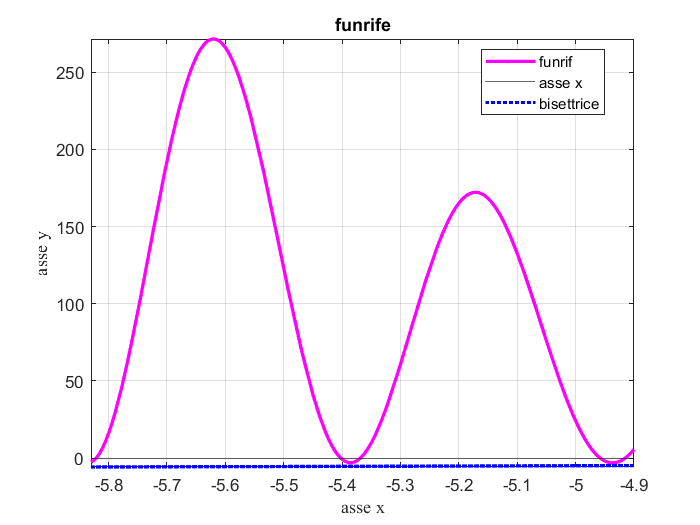

figure(10)
coordinate_bisettrice = linspace(-5.83,-4.9,10);
fplot(funrif,[-5.83,-4.9],"color" , 'magenta','LineWidth',2)

title('funrife'); % da un titolo alla nostra rappresentazione del grafico
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
yline(0)
grid on
hold on
plot(coordinate_bisettrice,coordinate_bisettrice,'b:','linewidth',2)%disegno la bisettrice sul grafico
hold off 
legend('funrif','asse x','bisettrice','location','best')

 ***Nel nostro caso la bisettrice non interseca con la funzione, dunque nell'intervallo A e B non sono presenti punti fissi****. Come richiesto dalla traccia stabilito che nel nostro intervallo A e B non sono presenti punti fissi, spieghiamo il procedimento per lo svolgimento richiesto nel caso ne avessimo trovato qualcuno. Il problema posto ci pone il calcolo del punto fisso attraverso fzero() senza utilizzare il metodo dei punti fissi. Dato che fzero() risolve il problema f(x)=0 possiamo utilizzare tale funzione per il calcolo del punto fisso ponendo quest'ultimo uguale a 0. Dato che la bisettrice ha ordinate ed ascisse uguali, punto fisso : f(x)=x,f(x)-x=0,fzero(funrif(x)-x,a). ****Propongo un esempio della nostra funzione in un intervallo diverso attarverso la funzione axis() dove la bisettrice interseca con la nostra funzioine.**** Il residuo lo si calcola facilmente così abs(funrif(puntofisso)-puntofisso). *

*La convergenza la si stabilisce: *

*abs(derivatadellafunzione(puntofisso))*

*se il risultato esce >1 la funzione diverge, vinceversa la funzione converge.*

***Per poter fare un esempio, utilizzeremo la funzione axis() per poter rappresentare un diverso tipo di intervallo che non e quello di riferimento per tanto non avrà i requisiti richiesti dei punti min e max e delle 5 f(x)=0.***

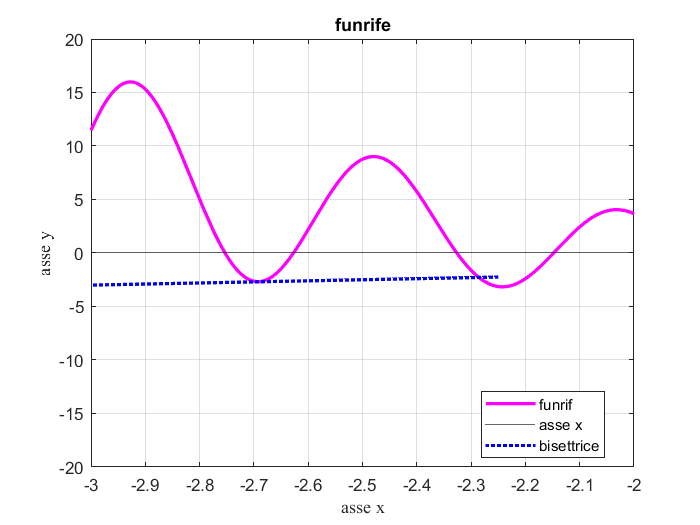

figure(11)
fplot(funrif,[-6,1],"color" , 'magenta','LineWidth',2)
title('funrife'); % da un titolo alla nostra rappresentazione del grafico
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
yline(0)
grid on
hold on
plot(linspace(-2.25,-3,10),linspace(-2.25,-3,10),'b:','linewidth',2)%disegno la bisettrice sul grafico
axis([-3 -2 -20 20]) %intervallo preso in considerazione
hold off 
legend('funrif','asse x','bisettrice','location','best')

*da notare come nell'intervallo -2.6 a -2.8 la bisettrice sfiori solamente la funzione creando l'illusione ottica di toccarla. Stabiliamo 1 punto fisso ad occhio circa nell'intervallo -2.35 a -2.25. Andiamo a vedere da più vicino il nostro punto fisso *

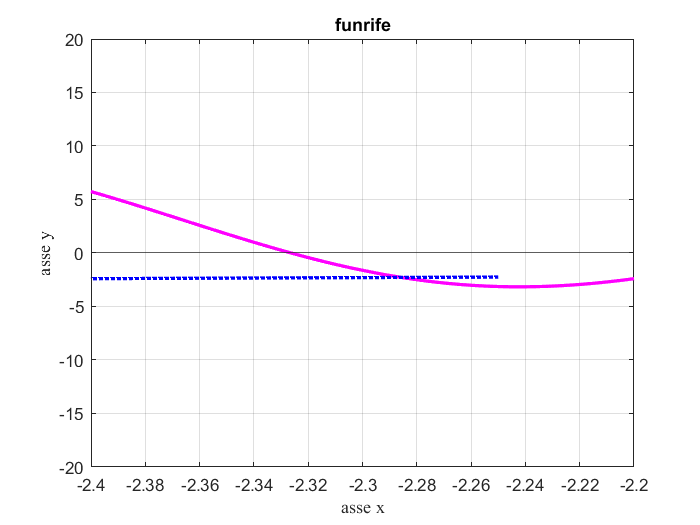

fplot(funrif,[-3, -2],"color" , 'magenta','LineWidth',2)
title('funrife'); % da un titolo alla nostra rappresentazione del grafico
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
yline(0)
grid on
hold on
plot(linspace(-2.25,-3,10),linspace(-2.25,-3,10),'b:','linewidth',2)%disegno la bisettrice sul grafico
axis([-2.4, -2.2, -20, 20])%ingrandiamo e prendiamo come riferimento un nuovo intervallo più preciso
hold off 

*procediamo nell'esempio con i calcoli richiesti dalla traccia.*

puntofisso = fzero(@(x)funrif(x)-x,-2.4)%calcoliamo il punto fisso essendo unico è il piu vicino all'estremo A,

puntofisso =   -2.285652147991613


residuopuntofisso = abs(funrif(puntofisso)-puntofisso)%calcoliamo il residuo

residuopuntofisso =      0


*da notare che il residuo è cosi piccolo da non essere rappresentabile.*

abs(derivata_prima(puntofisso))%definiamo la covergenza

ans =   40.176567085930387


*Da notare che il metodo divergerebbe in quanto la derivata calcolata in quel punto è maggiore di 1*

***Spiegazione di ciò che abbiamo fatto***

*Abbiamo Graficato la funzione e la bisettrice ed abbiamo stabilito come richiesto nella traccia se ci fossero punti fissi, non ne sono stati trovati, così abbiamo spiegato il metodo logico che avremmo applicato per poter svolgere i punti richiesti dalla traccia nel caso fossero stati trovati, poi successivamente abbiamo eseguito un esempio su un intervallo diverso  grazie alla funzione axis() mostrando sul grafico tale punto e calcolandolo tramite la function fzero() ed il suo residuo ed abbiamo definito se il metodo del punto fisso convergerebbe a tale punto..*

***Punto 7.***

**usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in **$[a,b]$**, con quattro chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo);**

`Procediamo`

%salvo gli intervalli di interesse in apposite variabili
maxsin2=- 5.7;
maxdes2=-5.5;
maxsin1= -5.2;
maxdes1=-5.1;
minsin1=-5;
mindes1=-4.9;
minsin2=-5.4;
mindes2=-5.3;
%calcolo il minimi e massimi della funzione
min1=fminbnd(funrif,minsin1,mindes1,optimset('TolX',1e-10))

min1 =   -4.936774022189030


min2=fminbnd(funrif,minsin2,mindes2,optimset('TolX',1e-10))

min2 =   -5.385574530297359


max1=fminbnd(@(x) -funrif(x),maxsin1,maxdes1,optimset('TolX',1e-10))

max1 =   -5.171390218520027


max2=fminbnd(@(x) -funrif(x),maxsin2,maxdes2,optimset('TolX',1e-10))

max2 =   -5.620182216662328


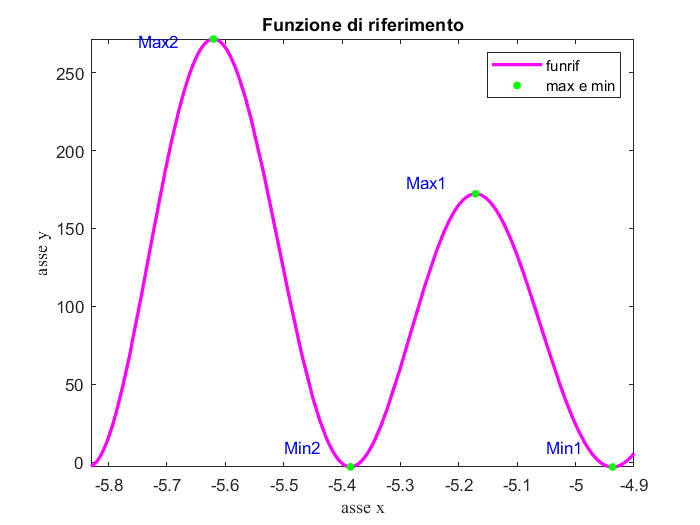

figure(13)
fplot(funrif,[-5.83,-4.9],"color" , 'magenta','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('Funzione di riferimento');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([min1, min2,max1,max2],[funrif(min1), funrif(min2),funrif(max1), funrif(max2)],'.','markersize',16,'color','green')% grafichiamo le nostri min e max  sul grafico
text(-5.05,10,'Min1', 'color','blue') %scriviamo ad occhio il nostro min
text(-5.5,10,'Min2', 'color','blue') %scriviamo ad occhio il nostro secondo min
text(-5.29,180,'Max1', 'color','blue') %scriviamo ad occhio il nostro max
text(-5.75,270,'Max2', 'color','blue') %scriviamo ad occhio il nostro secondo max
legend('funrif','max e min')
hold off

***Spiegazione di ciò che abbiamo fatto***

*attraverso la function fminbnd() abbiamo calcolato i punti di min e max, per calcolarci i punti di massimo non abbiamo fatto altro che passare la funzione di riferimento rovesciata Successivamente abbiamo graficato il tutto.*

***Punto 8***

**verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando **`axis([xmin xmax ymin ymax])`** ), e usando la **`fzero`** per *****calcolare tutti gli zeri della derivata; commentate i risultati ottenuti;***

*Si procede nel verificare graficando se i nostri punti di min e max corrispondono a dove la derivata è uguale a 0.*

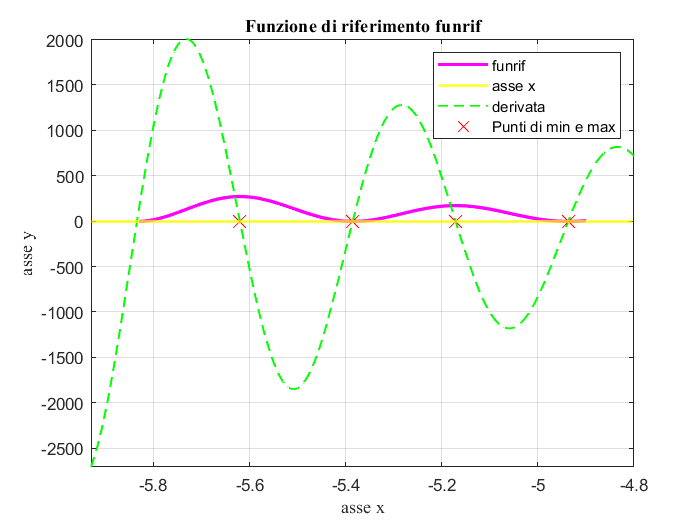

figure(14)
fplot(funrif,[-5.83,-4.9],'r',"color" , 'm','markersize',2,'LineWidth',2)%rappresenta il grafico
hold on   
grid on %crea la griglia
xlabel("asse x",'FontName','Times New Roman') %scrive l'asse x esternamente al grafico
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento funrif",'FontName','Times New Roman') %da un titolo al grafico
yline(0,'-','color','y','LineWidth',2)
fplot(derivata_prima,[-5.93,-4.8],"--","LineWidth",1,'color','green') %rappresenta la derivata sulla nostra funzione
plot([max1,max2,min1,min2],[derivata_prima(max1),derivata_prima(max2),derivata_prima(min1),derivata_prima(min2)],'X','markersize',11,'color','r')
hold off 
legend('funrif','asse x','derivata','Punti di min e max')

*Dal grafico risulta verificato, i nostri punti di min e max sono 0 della derivata.*

*Calcoliamo con fzero() gli 0 della derivata*

min1zero=fzero(derivata_prima,-5)

min1zero =   -4.936774021529700


abs(min1zero-min1)

ans =      6.593294799017713e-10


min1

min1 =   -4.936774022189030


*tra min1 e fzero()10 cifre decimale dovrebbero risultare uguali, invece ne risultano 8.*

max1zero=fzero(derivata_prima,-5.2)

max1zero =   -5.171390185309988


max1

max1 =   -5.171390218520027


abs(max1zero-max1)

ans =      3.321003916312293e-08


*tra max1 e il suo fzero() dovrebbero risultare 10 cifre uguali invece ne risultano 6.*

min2zero=fzero(derivata_prima,-5.4)

min2zero =   -5.385574530971326


min2

min2 =   -5.385574530297359


abs(min2zero-min2)

ans =      6.739666602584293e-10


*tra min2 e fzero 10 cifre decimale dovrebbero risultare uguali, invece ne risultano 9.*

max2zero=fzero(derivata_prima,-5.7)

max2zero =   -5.620182215823022


max2

max2 =   -5.620182216662328


abs(max2zero-max2)

ans =      8.393055139777061e-10


*10 cifre decimale dovrebbero risultare uguali, invece ne risultano 8.*

***I risultati Sono leggermente diversi da quelli attesi.***

*Deduzione...*

*Deduco che tale imprecisione sia data dalla funzione fminbnd() e che nonostante il tentativo di forzamento  della precisione a 10 cifre decimali  non riesce ad essere del tutto preciso e la minima precisione che di fatto a  garantire sono le 6 cifre decimali. Possiamo affermare che il risultato ottenuto non sia dell'accuratezza richiesta  1e-10 e che il procedimento sia giusto.*

***Spiegazione di ciò che abbiamo fatto***

*ci siamo calcolati gli 0 della derivata e per pura curiosità ne gho calcolato l'errore e li ho confrontati con i valori dati per esatti della funzione fminbd(), dato che sappiamo che fzero() da 16 cifre esatte riportando la massima accuratezza abbiamo dedotto ma non dato per certo che la funzione fminbd() non si distacchi di tanto dalla sua accuratezza di default e fa fatica a darne una superiore.*

**Punto 9**

**determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due minimi, e il metodo di Golden search (nostra function **`fmingolden`**) per i due massimi, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette; **

Per poter spiegare gli algoritmi dobbiamo innanzitutto dare la definizione di funzione unimodale:

Una funzione f è unimodale in [a,b] se esiste un unico numero r in [a,b] tale che f è decrescente in  [a,r] ed è crescente in [r,b].

**Spiegazione dell'algoritmo Fibonacci search**

*L'algoritmo di Fibonacci search consiste nel prendere due valori  come intervallo che racchiudono in essa la soluzione. All'interno dell'algoritmo da notare come viene scelto n in base all'accuratezza da noi scelta e di come poi successivamente viene richiamato la function fibonacci() su di essa. la scelta di c,d cerca di essere effettuata in maniera  da  garantire una riduzione ottimale dell’ampiezza degli intervalli che racchiudono a ogni passo la  soluzione. La successione di fibonacci indica l’n-simo numero della successione di Fibonacci. Fibonacci  è una successione di numeri interi in cui ciascun numero è la somma dei due precedenti, eccetto i primi due che sono, per definizione, 0 e 1. fibonacci(n) = fibonacci(n-1) + fibonacci(n-2), qualunque sia n>2. denominatore "den" contiene il k-esimo numero di Fibonacci consentendoci,  successivamente, di calcolare gli estremi "c" e "d". Le variabili ak e bk, contengono ad ogni passo, rispettivamente  l'estremo sinistro e l'estremo destro dell'intervallo.L’algoritmo di Fibonacci search è un metodo globale e con velocità di convergenza lineare.  parametri di input  sono: l'handle alla function che definisce la funzione che occorre minimizzare;  "a" estremo sinistro dell'intervallo che contiene la soluzione, e "b" estremo destro dello stesso intervallo;  delta_ass, l'accuratezza richiesta sulla soluzione;*

**Spiegazione dell'algoritmo fmingolden **

*La spiegazione di tale algoritmo è molto semplcie, Innanzitutto nel nostro caso andremo a definire la nuova variabile delta_ass con l'accuratezza richiesta e dichiareremo quindi una diversa variabile di nome simile che ci consente di avere una precisione tale in cui le prime 3 cifre decimali siano corrette.*

*delta_ass2 = 1e-3;*

*impostato una variabile che che mi garantisca la parte decimale corretta, si procederà con il richiamare la funzione. Prima di parlare di tale algoritmo mi consento di spiegare il metodo della ricerca aurea.*

*Il metodo della ricerca aurea o Golden Search può essere considerato come una variante del metodo di Fibonacci. Esso  si basa su risultati noti sulla successione dei numeri di Fibonacci, e per come noi gia sappiamo dal corso affrontato precedentemente in programmazione 1  la sezione aurea, per definizione, è il  limite per n->oo di F(N)/F(N-1). Quindi il rapporto tra due numeri di Fibonacci consecutivi tende al valore della  sezione aurea (circa 1.6180). L'idea del Golden Search è quindi molto semplice. Invece di determinare 'd' come fatto nella Fibonacci Search,  il Golden Search calcola 'd' ad ogni passo come *$\prime a\prime +\left\lbrack \textrm{phi}-1\right\rbrack *\left(b-a\right)\;$*, In maniera quasi analoga si  procede per calcolare 'c'. *

*Il metodo del Golden Search è leggermente meno efficiente del  metodo del Fibonacci Search, sebbene goda di una maggiore semplicità implementativa. Il golden search lo implementiamo in Matlab mediante la function "fmingolden". In input troviamo: l'handle alla function Matlab che definisce la funzione obiettivo;  l'estremo sinistro e destro dell'intervallo. Si utilizza un tecnica ricorsiva per l'implementazione dell'algoritmo. Il caso base della ricorsione si  che vengono utilizzate per determinare il nuovo punto 'c' e il nuovo punto 'd'.*

*imposto delta_ass2 uguale all'accuratezza richiesta.*

delta_ass2=1e-3;
minfibo1=fminfibo(funrif,minsin1,mindes1,delta_ass2)%richiamo la funzione

minfibo1 =   -4.936764705882354


min1

min1 =   -4.936774022189030


*Il risultato è quello atteso.*

minfibo2=fminfibo(funrif,-5.4,-5.37,delta_ass2)%richiamo la funzione

minfibo2 =   -5.385000000000000


min2

min2 =   -5.385574530297359


maxgolden1=fmingolden(@(x) -funrif(x),maxsin1,maxdes1,delta_ass2)%richiamo la funzione rovesciata

maxgolden1 =   -5.171226924187726


*Il risultato è quello atteso.*

max1

max1 =   -5.171390218520027


maxgolden2=fmingolden(@(x)-funrif(x),maxsin2,maxdes2,delta_ass2)%richiamo la funzione

maxgolden2 =   -5.620281236504081


*Il risultato è quello atteso.*

max2

max2 =   -5.620182216662328


*Il risultato è quello atteso.*

`Grafico in onore di fibonacci`

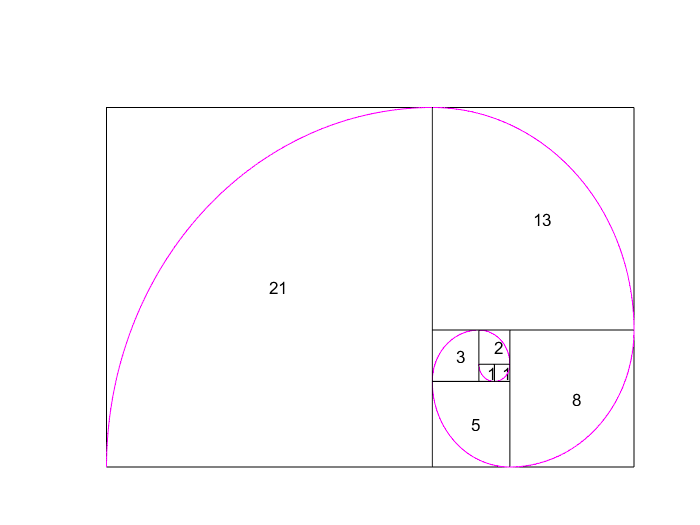

figure(15)
x = 0;
y = 1;
syms v u

axis off
hold on

for n = 1:8

    a = fibonacci(n);

    % definisco quadrati ed archi
    switch mod(n,4)
        case 0
            y = y - fibonacci(n-2);
            x = x - a;
            eqnArc = (u-(x+a))^2 + (v-y)^2 == a^2;
        case 1
            y = y - a;
            eqnArc = (u-(x+a))^2 + (v-(y+a))^2 == a^2;
        case 2
            x = x + fibonacci(n-1);
            eqnArc = (u-x)^2 + (v-(y+a))^2 == a^2;
        case 3
            x = x - fibonacci(n-2);
            y = y + fibonacci(n-1);
            eqnArc = (u-x)^2 + (v-y)^2 == a^2;
    end

    % disegno quadrato
    pos = [x y a a];
    rectangle('Position', pos)

    % aggiunta dei numeri di Fibonacci 
    xText = (x+x+a)/2;
    yText = (y+y+a)/2;
    text(xText, yText, num2str(a))

    % Disegno arco
    interval = [x x+a y y+a];
    fimplicit(eqnArc, interval, 'm')

end

**Spiegazione di ciò che abbiamo fatto**

*Abbiamo inizialmente spiegato brevemente i due algoritmi utilizzati, successivamente attraverso i due metodi richiesti dalla traccia abbiamo calcolato i due min con la function fminfibo() e i due max con la function fmingolden. Alla fine del procedimento richiesto dalla traccia in onore di fibonacci abbiamo graficato la sua successione.*

**Punto 10**

**considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati;**

*Procedo Con il calcolo degli errori assoluti*

errminfibo1=abs(minfibo1-min1)%calcolo l'errore assoluto

errminfibo1 =      9.316306676332431e-06


errminfibo1<delta_ass2

ans = logical
   1


errminfibo2=abs(minfibo2-min2)%calcolo l'errore assoluto

errminfibo2 =      5.745302973592104e-04


errminfibo2<delta_ass2

ans = logical
   1


errmaxgolden1=abs(maxgolden1-max1)%calcolo l'errore assoluto

errmaxgolden1 =      1.632943323004454e-04


errmaxgolden1<delta_ass2

ans = logical
   1


errmaxgolden2=abs(maxgolden2-max2)%calcolo l'errore assoluto

errmaxgolden2 =      9.901984175275658e-05


errmaxgolden2<delta_ass2

ans = logical
   1


*Gli errori sono tutti minori dell'accuratezza richiesta.*

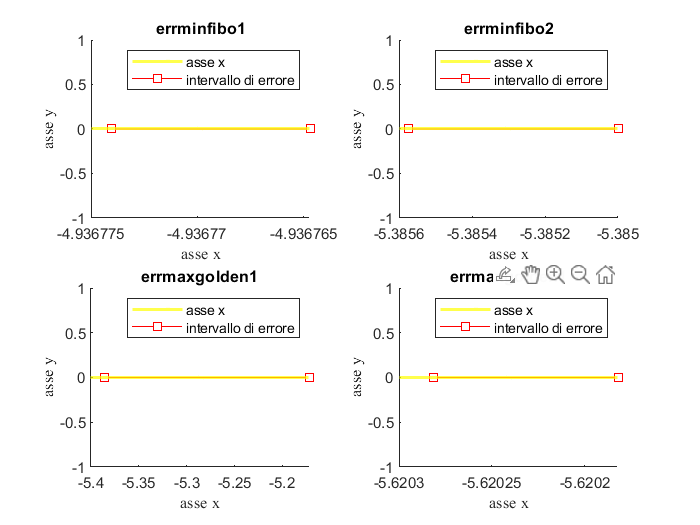

figure(16)
subplot(221),yline(0,'color','y','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('errminfibo1');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([minfibo1,min1],[0,0],'-s','color','r','MarkerFaceColor','w','markersize',6)
hold off
legend('asse x','intervallo di errore')
subplot(222),yline(0,'color','y','LineWidth',2')% permette di esporre tracciati multipli nella stessa finestra
title('errminfibo2');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([minfibo2,min2],[0,0],'-s','color','r','MarkerFaceColor','w','markersize',6)
hold off
legend('asse x','intervallo di errore')
subplot(223),yline(0,'color','y','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('errmaxgolden1');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([maxgolden1,min2],[0,0],'-s','color','r','MarkerFaceColor','w','markersize',6)
hold off
legend('asse x','intervallo di errore')
subplot(224),yline(0,'y','LineWidth',2)% permette di esporre tracciati multipli nella stessa finestra
title('errmaxgolden1');%diamo un titolo
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot([maxgolden2,max2],[0,0],'-s','color','r','MarkerFaceColor','w','markersize',6)
hold off
legend('asse x','intervallo di errore')

*Da notare Gli intervalli di errori*

***Spiegazione di ciò che è stato  fatto***

*Abbiamo calcolato gli errori assoluti tra le funzioni da noi utilizzate e il risultato dato per esatto da fminbd() e successivamente ne abbiamo confrontato i valori con l'accuratezza richiesta successivamente abbiamo graficato gli errori.*

**Riccardo Andrea Spinosa**